# MAS416 - Tutorial 7

## Problem 1a)

clc; clear all; close all;

Jm = 0.8; % kgm^2
J1 = 0.1; % kgm^2
J2 = 1.5; % kgm^2
Jd = 8; % kgm^2

m = 10000; % kg
g = 9.81; % m/s
r1 = 80/10^3; % m
r2 = 480/10^3; % m
rd = 600/10^3; % m
L0 = 10; % m

tr = 2; % s
thetaDot_ref_min = 0; % rad/s
thetaDot_ref_max = 12; % rad/s

Mm_max = 2000; % Nm
Mm_min = 0; % Nm

tau_tq = 0.15; % s

simTime = 4; % s
dt = 10^-6; % s
t = 0; % s
idx = 1; % Counter

% PID constants
Kp = 10000;
tau_i = 0.5;
err_int_thetaDot = 0;
theta = 0;
thetaDot = 0;

while(t <= simTime)
    % Calculations

    % Ramping
    if(t < tr)
        thetaDot_ref = t/tr * thetaDot_ref_max;
    else
        thetaDot_ref = thetaDot_ref_max;
    end

    % Error
    err_thetaDot = thetaDot_ref - thetaDot;

    % Moment
    Mm = Kp*err_thetaDot + Kp/tau_i * err_int_thetaDot;

    % Moment saturation
    if(Mm >= Mm_max)
        Mm = Mm_max;
    elseif(Mm <= Mm_min)
        Mm = Mm_min;
    end

    % Gear ratio:
    gear = r2/r1;

    % Kinetic energy from motor to drum
    % E_kin_m_g1 = 1/2 * Jm * thetaDot^2 + 1/2 * J1 * thetaDot^2; % Motor and gear 1 inertia
    % E_kin_g2_g1 = 1/2 * J2 * (thetaDot/gear)^2 + 1/2 * J1 * (thetaDot/gear)^2; % Gear 2 to gear 1 inertia
    % E_kin_g2_d = 1/2 * J2 * (thetaDot/gear^2)^2 + 1/2 * Jd * (thetaDot/gear^2)^2; % Gear 2 to drum inertia
    
    % Kinetic energy from load
    %v_mass = rd*thetaDot/gear^2; % drum radius * speed of drum
    %E_kin_L = 1/2 * m * v_mass^2;

    Jeff = Jm + J1 + (J2 + J1)/gear^2 + (J2 + Jd + m*rd^2)/gear^4;
    Meff = (m*g*rd)/gear^2;

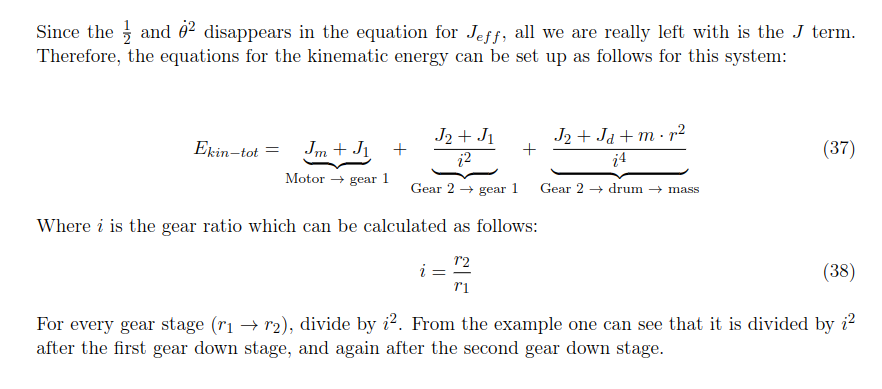

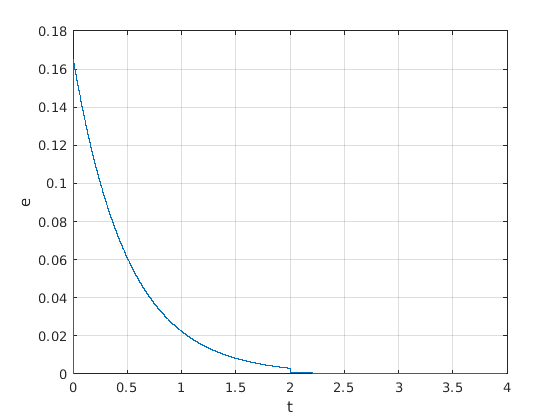

    % Angular acceleration
    thetaDotDot = (Mm-Meff)/Jeff;

    % Logging
    t_plt(idx) = t;
    err_thetaDot_plt(idx) = err_thetaDot;
    theta_plt(idx) = theta;

    % Time integration
    thetaDot = thetaDot + thetaDotDot * dt;
    theta = theta + thetaDot * dt;
    err_int_thetaDot = err_int_thetaDot + err_thetaDot * dt;

    % Updating variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, err_thetaDot_plt)
grid
xlabel("t")
ylabel("e")

## Problem 1b)

t = 0; % s
idx = 1; % Counter

% PID constants
Kp = 10000;
tau_i = 0.5;
err_int_thetaDot = 0;
theta = 0;
thetaDot = 0;
Mm = 0;

while(t <= simTime)
    % Calculations

    % Ramping
    if(t < tr)
        thetaDot_ref = t/tr * thetaDot_ref_max;
    else
        thetaDot_ref = thetaDot_ref_max;
    end

    % Error
    err_thetaDot = thetaDot_ref - thetaDot;

    % Moment reference
    Mm_ref = Kp*err_thetaDot + Kp/tau_i * err_int_thetaDot;

    % Moment saturation (of actual measured moment)
    if(Mm >= Mm_max)
        Mm = Mm_max;
    elseif(Mm <= Mm_min)
        Mm = Mm_min;
    end

    % Gear ratio:
    gear = r2/r1;

    % Kinetic energy from motor to drum
    % E_kin_m_g1 = 1/2 * Jm * thetaDot^2 + 1/2 * J1 * thetaDot^2; % Motor and gear 1 inertia
    % E_kin_g2_g1 = 1/2 * J2 * (thetaDot/gear)^2 + 1/2 * J1 * (thetaDot/gear)^2; % Gear 2 to gear 1 inertia
    % E_kin_g2_d = 1/2 * J2 * (thetaDot/gear^2)^2 + 1/2 * Jd * (thetaDot/gear^2)^2; % Gear 2 to drum inertia
    
    % Kinetic energy from load
    %v_mass = rd*thetaDot/gear^2; % drum radius * speed of drum
    %E_kin_L = 1/2 * m * v_mass^2;

    Jeff = Jm + J1 + (J2 + J1)/gear^2 + (J2 + Jd + m*rd^2)/gear^4;
    Meff = (m*g*rd)/gear^2;

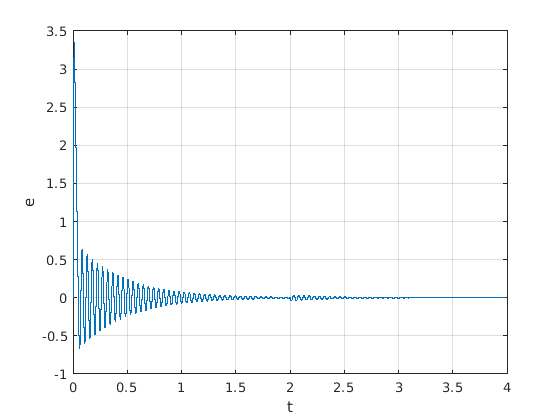

    % Angular acceleration
    thetaDotDot = (Mm-Meff)/Jeff;

    % Torque buildup
    MmDot = 1/tau_tq * (Mm_ref - Mm);

    % Logging
    t_plt(idx) = t;
    err_thetaDot_plt(idx) = err_thetaDot;
    theta_plt(idx) = theta;

    % Time integration
    Mm = Mm + MmDot * dt;
    thetaDot = thetaDot + thetaDotDot * dt;
    theta = theta + thetaDot * dt;
    err_int_thetaDot = err_int_thetaDot + err_thetaDot * dt;

    % Updating variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, err_thetaDot_plt)
grid
xlabel("t")
ylabel("e")

## Problem 1c)

t = 0; % s
idx = 1; % Counter

% PID constants
Kp = 1500;
tau_i = 0.8;
err_int_thetaDot = 0;
theta = 0;
thetaDot = 0;
Mm = 0;
thetaDot_measured = 0;

samplingTime = 0.001; % s (1000Hz = 0.001s // Hz = 1/s)
t_lastSample = 0; % s

while(t <= simTime)
    % Calculations
    tWait = t - t_lastSample;

    if(tWait >= samplingTime)
        thetaDot_measured = thetaDot;
        t_lastSample = t;
    end

    % Ramping
    if(t < tr)
        thetaDot_ref = t/tr * thetaDot_ref_max;
    else
        thetaDot_ref = thetaDot_ref_max;
    end

    % Error
    err_thetaDot = thetaDot_ref - thetaDot_measured;

    % Moment reference
    Mm_ref = Kp*err_thetaDot + Kp/tau_i * err_int_thetaDot;

    % Moment saturation (of actual measured moment)
    if(Mm >= Mm_max)
        Mm = Mm_max;
    elseif(Mm <= Mm_min)
        Mm = Mm_min;
    end

    % Gear ratio:
    gear = r2/r1;

    % Kinetic energy from motor to drum
    % E_kin_m_g1 = 1/2 * Jm * thetaDot^2 + 1/2 * J1 * thetaDot^2; % Motor and gear 1 inertia
    % E_kin_g2_g1 = 1/2 * J2 * (thetaDot/gear)^2 + 1/2 * J1 * (thetaDot/gear)^2; % Gear 2 to gear 1 inertia
    % E_kin_g2_d = 1/2 * J2 * (thetaDot/gear^2)^2 + 1/2 * Jd * (thetaDot/gear^2)^2; % Gear 2 to drum inertia
    
    % Kinetic energy from load
    %v_mass = rd*thetaDot/gear^2; % drum radius * speed of drum
    %E_kin_L = 1/2 * m * v_mass^2;

    Jeff = Jm + J1 + (J2 + J1)/gear^2 + (J2 + Jd + m*rd^2)/gear^4;
    Meff = (m*g*rd)/gear^2;

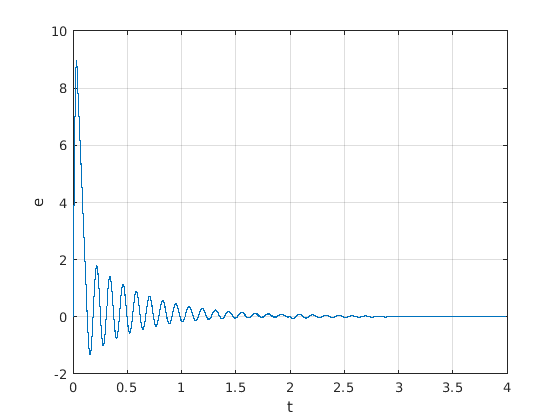

    % Angular acceleration
    thetaDotDot = (Mm-Meff)/Jeff;

    % Torque buildup
    MmDot = 1/tau_tq * (Mm_ref - Mm);

    % Logging
    t_plt(idx) = t;
    err_thetaDot_plt(idx) = err_thetaDot;
    theta_plt(idx) = theta;
    
    % Time integration
    Mm = Mm + MmDot * dt;
    thetaDot = thetaDot + thetaDotDot * dt;
    theta = theta + thetaDot * dt;
    err_int_thetaDot = err_int_thetaDot + err_thetaDot * dt;

    % Updating variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, err_thetaDot_plt)
grid
xlabel("t")
ylabel("e")